# a

syms t
y=@(t)-1/4*cos(4*t); %Define function
T=vectorize(taylor(y(t),t,2)); %Create taylor polynomial as a matlab expression
t=0:0.1:2;
p=eval(T)

p =    -0.2500   -0.2303   -0.1742   -0.0906    0.0073    0.1040    0.1843    0.2356    0.2496    0.2242    0.1634    0.0768   -0.0219   -0.1171   -0.1939   -0.2400   -0.2483   -0.2173   -0.1521   -0.0628    0.0364


p(end)

ans = 0.0364

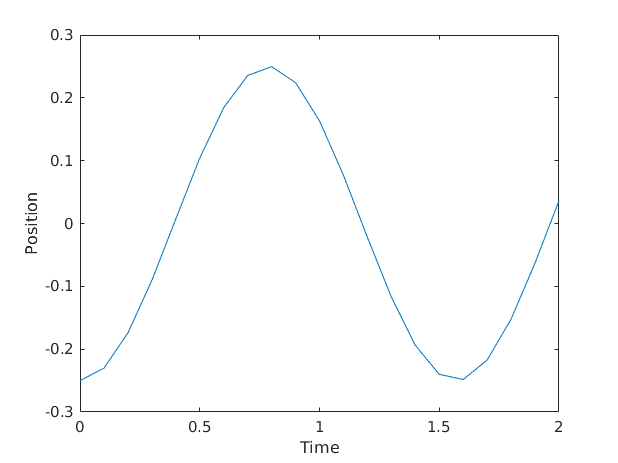

plot(t, p)
xlabel('Time'); ylabel('Position')
print('eps/topic8_a.eps','-depsc')

# b

h=0.05; N=40; y=zeros(1,41); y(1)=-0.25;
t=0:h:2;
dy=@(t)sin(4*t);
for n=1:N
    y(n+1)=y(n)+h*dy(t(n));
end
y(end)

ans = 0.0107

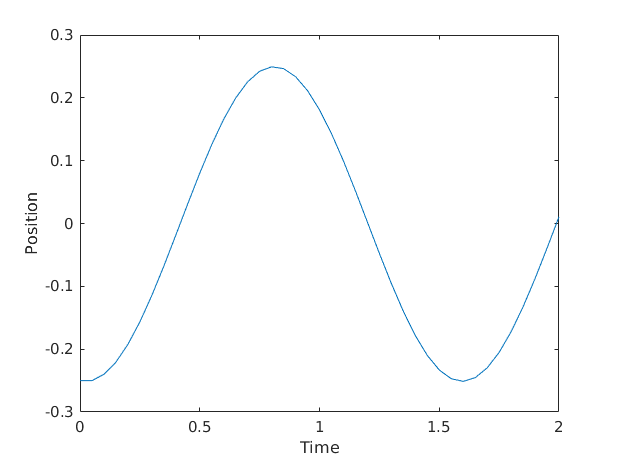

plot(t,y)
xlabel('Time'); ylabel('Position')

print('eps/topic8_b.eps','-depsc')

Error using matlab.graphics.internal.name (line 101)
Cannot create output file 'eps/topic8_b.eps'.

Error in print (line 71)
pj = matlab.graphics.internal.name( pj );